# Uso di una rete pre-addestrata per classificare dati presi dal dataset SHVN

In questo script viene utilizzata una rete neurale convoluzionale (CNN) pre-addestrata per la classificazione delle cifre presenti nel dataset SVHN (Street View House Numbers). 

Questo dataset è comunemente utilizzato per la valutazione delle prestazioni degli algoritmi di riconoscimento di cifre in condizioni reali. SVHN contiene immagini di cifre provenienti da numeri civici fotografati da Google Street View.

Il dataset SVHN contiene oltre 600.000 immagini di cifre, suddivise in un set di addestramento, un set di test e un set di extra training. Le immagini sono a colori e hanno dimensioni di 32x32 pixel. Ogni immagine contiene una cifra da 0 a 9.

### Obiettivo

L'obiettivo principale di questo progetto è quello di sfruttare una rete neurale convoluzionale preaddestrata per migliorare l'accuratezza della classificazione delle immagini del dataset SVHN. 

## Step by step:

### **Caricamento del Dataset**

Viene definito il percorso della directory in cui sarà salvato il dataset SVHN, utilizzando una directory temporanea del sistema.

% Specifica la directory del dataset
svhnDatasetPath = fullfile(tempdir, 'SVHN');

Controlla se la directory specificata esiste. Se non esiste, la crea.

if ~exist(svhnDatasetPath, 'dir')
    mkdir(svhnDatasetPath);
end

Definisce gli URL da cui scaricare i dati di training e di test del dataset SVHN.

urlTrain = 'http://ufldl.stanford.edu/housenumbers/train_32x32.mat';
urlTest = 'http://ufldl.stanford.edu/housenumbers/test_32x32.mat';

Definisce i percorsi completi dei file di training e test nella directory locale.

% Percorsi dei file
trainFile = fullfile(svhnDatasetPath, 'train_32x32.mat');
testFile = fullfile(svhnDatasetPath, 'test_32x32.mat');

Scarica i file se non sono già presenti.

if ~exist(trainFile, 'file')
    disp('Scaricamento del dataset di training SVHN...');
    websave(trainFile, urlTrain);
end

if ~exist(testFile, 'file')
    disp('Scaricamento del dataset di test SVHN...');
    websave(testFile, urlTest);
end

Carica i dati di training e test chiamando la funzione `loadSVHNData` e passa la directory del dataset come argomento.

[trainingImages, trainingLabels, testImages, testLabels] = loadSVHNData(svhnDatasetPath);

La funzione `loadSVHNData` è definita a valle del live script.

### Modifica le dimensioni di input e l'aumento dei dati

In questa parte si preparano le immagini del dataset SVHN per essere compatibili con il modello di deep learning pre-addestrato che si vuole utilizzare. Si ridimensionano le immagini di training e di test alla dimensione richiesta (224x224x3) e si creano dei datastore per gestire queste immagini durante l'addestramento e la valutazione del modello. 

% Dimensione di input richiesta dal modello pre-addestrato
inputSize = [224 224 3];

% Ridimensiona le immagini per il training e il test
trainingImagesResized = resizeImages(trainingImages, inputSize);
testImagesResized = resizeImages(testImages, inputSize);

Questo tipo di `datastore` è utile per gestire grandi quantità di dati di immagine e applicare operazioni di pre-elaborazione o augmentazione durante l'addestramento del modello.

augmentedTrainImages = augmentedImageDatastore(inputSize, trainingImagesResized, trainingLabels);
augmentedTestImages = augmentedImageDatastore(inputSize, testImagesResized, testLabels);

La funzione `resizeImages` è definita a valle del live script.

### Modifica la rete pre-addestrata per adattarsi al dataset SVHN

Il codice carica il modello ResNet-18 pre-addestrato e modifica gli ultimi livelli per adattarsi a un nuovo problema di classificazione con 10 classi, come richiesto dal dataset SVHN. Specificamente, sostituisce il livello completamente connesso finale e il livello di classificazione con nuovi livelli che corrispondono al numero di classi del nuovo problema. Questo processo è noto come "transfer learning", dove si riutilizzano i pesi pre-addestrati di una rete su un nuovo problema, adattando solo gli ultimi strati.

Si carica il modello di rete neurale convoluzionale pre-addestrato ResNet-18. Questo modello è stato addestrato su ImageNet, un ampio dataset di immagini, e contiene pesi pre-addestrati.

net = resnet18;

Si definisce il numero di classi nel problema di classificazione SVHN, che è 10 (da 0 a 9).

nClasses = 10;

SI converte il modello caricato in un grafo di livelli (`layerGraph`) che consente di modificare la struttura della rete.

layergraph = layerGraph(net);

Si crea un nuovo livello completamente connesso (`fullyConnectedLayer`) con il numero di neuroni pari al numero di classi. 

Si sostituisce il livello completamente connesso esistente nella rete originale con il nuovo livello completamente connesso creato in precedenza.

newLearnableLayer = fullyConnectedLayer(nClasses, 'Name', 'new_fc', 'WeightLearnRateFactor', 10, 'BiasLearnRateFactor', 10);
layergraph = replaceLayer(layergraph, 'fc1000', newLearnableLayer);

Si crea un nuovo livello di classificazione (`classificationLayer`).

Si sostituisce il livello di classificazione esistente (`ClassificationLayer_predictions`) nella rete originale con il nuovo livello di classificazione.

newClassLayer = classificationLayer('Name', 'new_classoutput');
layergraph = replaceLayer(layergraph, 'ClassificationLayer_predictions', newClassLayer);

### Configurazione degli iperparametri

Questo codice MATLAB configura gli iperparametri per l'addestramento di una rete neurale utilizzando il metodo di ottimizzazione `Stochastic Gradient Descent with Momentum (SGDM).`

options = trainingOptions('sgdm', ...
    'MiniBatchSize', 64, ... 
    'MaxEpochs', 3, ...
    'InitialLearnRate', 1e-3, ...
    'Verbose', false, ...
    'Plots', 'training-progress');

### Allenamento e Valutazione

Il codice addestra una rete neurale utilizzando i dati di addestramento e le opzioni specificate, poi valuta le prestazioni del modello sul set di test. Le etichette predette per le immagini di test vengono confrontate con le etichette reali per calcolare l'accuratezza del modello, che viene infine visualizzata come percentuale. Questo processo consente di misurare quanto bene il modello addestrato riesce a generalizzare sui dati non visti.

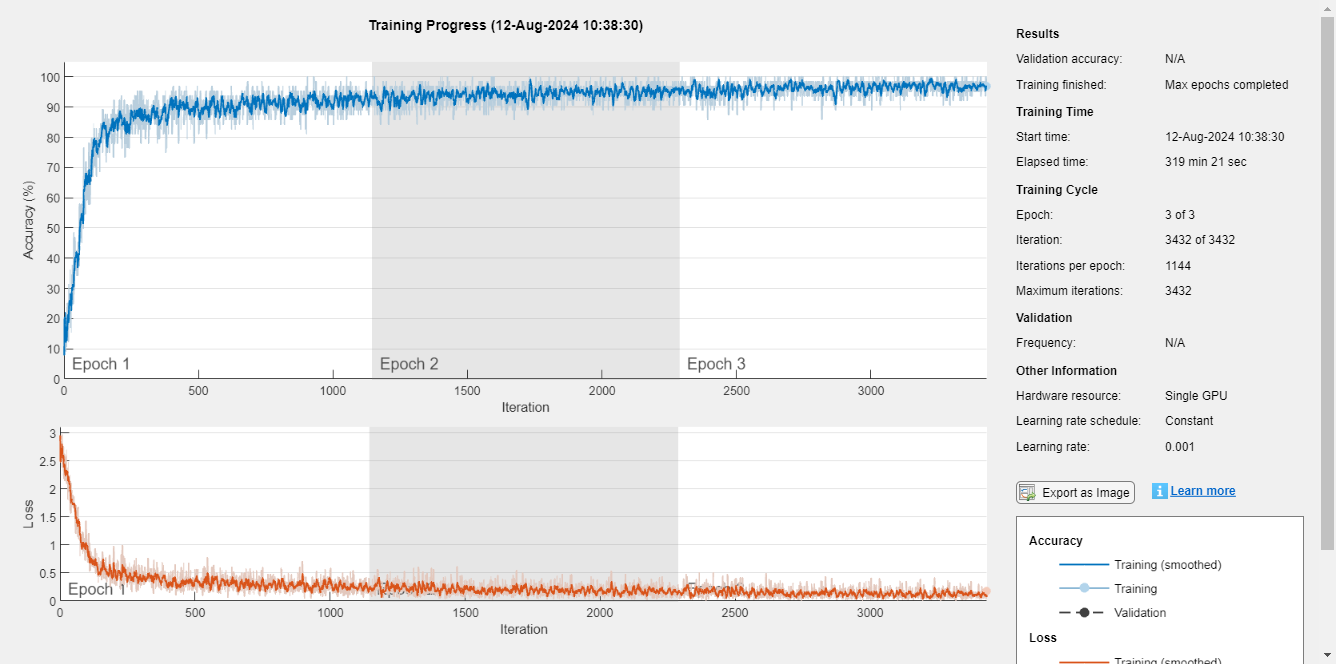

% Allenamento del modello
trainedNet = trainNetwork(augmentedTrainImages, layergraph, options);


% Valutazione del modello
YPred = classify(trainedNet, augmentedTestImages);
accuracy = mean(YPred == testLabels);
disp(['Accuratezza sul set di test: ', num2str(accuracy * 100), '%']);

Accuratezza sul set di test: 94.9293%


# Funzioni:

## loadSVHNData

La funzione prende un argomento di input il percorso della directory contenente i file del dataset SVHN e restituisce quattro variabili.

La funzione carica e prepara i dati del dataset SVHN dai file .mat. Essa legge i dati di training e test, riorganizza le dimensioni delle immagini per un formato standard e converte le etichette in variabili categoriali. 

function [XTrain, YTrain, XTest, YTest] = loadSVHNData(svhnData)
    % Carica i dati di training
    trainData = load(fullfile(svhnData, 'train_32x32.mat'));
    XTrain = permute(trainData.X, [2, 1, 3, 4]); % Cambia la dimensione da (32, 32, 3, N) a (32, 32, 3, N)
    YTrain = trainData.y;

    % Carica i dati di test
    testData = load(fullfile(svhnData, 'test_32x32.mat'));
    XTest = permute(testData.X, [2, 1, 3, 4]); % Cambia la dimensione da (32, 32, 3, N) a (32, 32, 3, N)
    YTest = testData.y;

    YTrain = categorical(YTrain);
    YTest = categorical(YTest);
end

## resizeImages

La funzione prende un insieme di immagini e le ridimensiona alla dimensione specificata da `newSize`. Inizialmente, determina il numero di immagini presenti, poi crea un array vuoto per memorizzare le immagini ridimensionate. Utilizza un ciclo `for` per ridimensionare ciascuna immagine individualmente usando la funzione `imresize` e memorizza le immagini ridimensionate nell'array predefinito. 

function resizedImgs = resizeImages(images, newSize)
    nImages = size(images, 4);
    resizedImgs = zeros([newSize, nImages], 'like', images);
    for i = 1:nImages
        resizedImgs(:,:,:,i) = imresize(images(:,:,:,i), newSize(1:2));
    end
end